# Actividad 1: Mapeo de coordenadas

**Paola Rojas Domínguez A01737136**

Este código implementa una serie de operaciones matemáticas para analizar la posición y la orientación de un robot móvil en un espacio bidimensional.

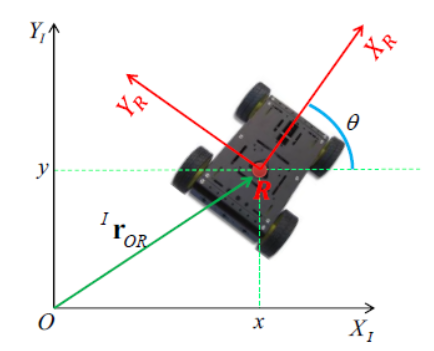

Se utilizan transformaciones de coordenadas entre el sistema de referencia inercial y el sistema de referencia local del robot. Además, se verifica la correcta conversión entre estos sistemas mediante el uso de matrices de rotación.

## Inicialización y Declaración de Variables

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores. Posteriormente, se declaran las variables simbólicas, esenciales para realizar cálculos simbólicos y analíticos.

clear all
close all
clc

tic
%Declaración de variables simbólicas
syms x(t) y(t) th(t) t %Grados de Libertad del robot móvil

Se define el vector de coordenadas generalizadas, que representa la posición del robot en el sistema de referencia inercial.

xi_inercial = [x; y; th];
disp('Coordenadas generalizadas'); pretty(xi_inercial);

Coordenadas generalizadas
/  x(t) \
|       |
|  y(t) |
|       |
\ th(t) /



Se calcula el vector de velocidades generalizadas, obteniendo la derivada temporal de las coordenadas.

xip_inercial = diff(xi_inercial, t);
disp('Velocidades generalizadas'); pretty(xip_inercial);

Velocidades generalizadas
/   d      \
|  -- x(t) |
|  dt      |
|          |
|   d      |
|  -- y(t) |
|  dt      |
|          |
|  d       |
| -- th(t) |
\ dt       /



Se definen los vectores posición (indican la posición relativa de una articulación) y las matrices de rotación (describen la orientación de un sistema de coordenadas respecto a otro) para cada articulación.

%Definimos mi vector de posición y matriz de rotación
P(:,:,1)= [x; y; th]; %Viene siendo "xi_inercial"

%Matriz de rotación alrededor del eje z....
R(:,:,1)= [cos(th) -sin(th)  0;
           sin(th)  cos(th)  0;
           0        0        1];

Se realiza la transformación del marco de referencia global al local

xi_local = R(:,:,1) * P(:,:,1);

## a) (-5, 9, -2°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xa = -5; % Posición inicial eje x
ya = 9; % Posición inicial eje y
tha = -2 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_a= [xa; ya; 0];
Rot_a= [cos(tha) -sin(tha)  0;
        sin(tha)  cos(tha)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_a = Rot_a * Pos_a

xi_local_a =    -4.6829
    9.1690
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_a(1)^2 + xi_local_a(2)^2)

magnitud = 10.2956

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_a = inv(Rot_a);
xi_inercial_a = inv_Rot_a * xi_local_a

xi_inercial_a =    -5.0000
    9.0000
         0


## b) (-3, 8, 63°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xb = -3; % Posición inicial eje x
yb = 8; % Posición inicial eje y
thb = 63 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_b= [xb; yb; 0];
Rot_b= [cos(thb) -sin(thb)  0;
        sin(thb)  cos(thb)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_b = Rot_b * Pos_b

xi_local_b =    -8.4900
    0.9589
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_b(1)^2 + xi_local_b(2)^2)

magnitud = 8.5440

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_b = inv(Rot_b);
xi_inercial_b = inv_Rot_b * xi_local_b

xi_inercial_b =     -3
     8
     0


## c) (5, -2, 90°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xc = 5; % Posición inicial eje x
yc = -2; % Posición inicial eje y
thc = pi/2;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_c= [xc; yc; 0];
Rot_c= [cos(thc) -sin(thc)  0;
        sin(thc)  cos(thc)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_c = Rot_c * Pos_c

xi_local_c =     2.0000
    5.0000
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_c(1)^2 + xi_local_c(2)^2)

magnitud = 5.3852

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_c = inv(Rot_c);
xi_inercial_c = inv_Rot_c * xi_local_c

xi_inercial_c =      5
    -2
     0


## d) (0, 0, 180°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xd = 0; % Posición inicial eje x
yd = 0; % Posición inicial eje y
thd = pi;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_d= [xd; yd; 0];
Rot_d= [cos(thd) -sin(thd)  0;
        sin(thd)  cos(thd)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_d = Rot_d * Pos_d

xi_local_d =      0
     0
     0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_d(1)^2 + xi_local_d(2)^2)

magnitud = 0

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_d = inv(Rot_d);
xi_inercial_d = inv_Rot_d * xi_local_d

xi_inercial_d =      0
     0
     0


## e) (-6, 3, -55°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xe = -6; % Posición inicial eje x
ye = 3; % Posición inicial eje y
the = -55 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_e= [xe; ye; 0];
Rot_e= [cos(the) -sin(the)  0;
        sin(the)  cos(the)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_e = Rot_e * Pos_e

xi_local_e =    -0.9840
    6.6356
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_e(1)^2 + xi_local_e(2)^2)

magnitud = 6.7082

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_e = inv(Rot_e);
xi_inercial_e = inv_Rot_e * xi_local_e

xi_inercial_e =    -6.0000
    3.0000
         0


## f) (10, -2, 45°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

%Defino coordenadas inerciales para un tiempo 1
xf = 10; % Posición inicial eje x
yf = -2; % Posición inicial eje y
thf = pi/4;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_f= [xf; yf; 0];
Rot_f= [cos(thf) -sin(thf)  0;
        sin(thf)  cos(thf)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_f = Rot_f * Pos_f

xi_local_f =     8.4853
    5.6569
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_f(1)^2 + xi_local_f(2)^2)

magnitud = 10.1980

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_f = inv(Rot_f);
xi_inercial_f = inv_Rot_f * xi_local_f

xi_inercial_f =     10
    -2
     0


## g) (9, 1, 88°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xg = 9; % Posición inicial eje x
yg = 1; % Posición inicial eje y
thg = 88 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_g= [xg; yg; 0];
Rot_g= [cos(thg) -sin(thg)  0;
        sin(thg)  cos(thg)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_g = Rot_g * Pos_g

xi_local_g =    -0.6853
    9.0294
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_g(1)^2 + xi_local_g(2)^2)

magnitud = 9.0554

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_g = inv(Rot_g);
xi_inercial_g = inv_Rot_g * xi_local_g

xi_inercial_g =      9
     1
     0


## h) (5, 2, 33°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xh = 5; % Posición inicial eje x
yh = 2; % Posición inicial eje y
thh = 33 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_h= [xh; yh; 0];
Rot_h= [cos(thh) -sin(thh)  0;
        sin(thh)  cos(thh)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_h = Rot_h * Pos_h

xi_local_h =     3.1041
    4.4005
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_h(1)^2 + xi_local_h(2)^2)

magnitud = 5.3852

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_h = inv(Rot_h);
xi_inercial_h = inv_Rot_h * xi_local_h

xi_inercial_h =      5
     2
     0


## i) (-1, -1, 21°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xi = -1; % Posición inicial eje x
yi = -1; % Posición inicial eje y
thi = 21 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_i= [xi; yi; 0];
Rot_i= [cos(thi) -sin(thi)  0;
        sin(thi)  cos(thi)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_i = Rot_i * Pos_i

xi_local_i =    -0.5752
   -1.2919
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_i(1)^2 + xi_local_i(2)^2)

magnitud = 1.4142

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_i = inv(Rot_i);
xi_inercial_i = inv_Rot_i * xi_local_i

xi_inercial_i =    -1.0000
   -1.0000
         0


## j) (6, 4, -40°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xj = 6; % Posición inicial eje x
yj = 4; % Posición inicial eje y
thj = -40 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_j= [xj; yj; 0];
Rot_j= [cos(thj) -sin(thj)  0;
        sin(thj)  cos(thj)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_j = Rot_j * Pos_j

xi_local_j =     7.1674
   -0.7925
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_j(1)^2 + xi_local_j(2)^2)

magnitud = 7.2111

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_j = inv(Rot_j);
xi_inercial_j = inv_Rot_j * xi_local_j

xi_inercial_j =     6.0000
    4.0000
         0


## k) (5, 7, 72°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xk = 5; % Posición inicial eje x
yk = 7; % Posición inicial eje y
thk = 72 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_k= [xk; yk; 0];
Rot_k= [cos(thk) -sin(thk)  0;
        sin(thk)  cos(thk)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_k = Rot_k * Pos_k

xi_local_k =    -5.1123
    6.9184
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_k(1)^2 + xi_local_k(2)^2)

magnitud = 8.6023

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_k = inv(Rot_k);
xi_inercial_k = inv_Rot_k * xi_local_k

xi_inercial_k =      5
     7
     0


## l) (7, 7, 30°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xl = 7; % Posición inicial eje x
yl = 7; % Posición inicial eje y
thl = pi/6;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_l= [xl; yl; 0];
Rot_l= [cos(thl) -sin(thl)  0;
        sin(thl)  cos(thl)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_l = Rot_l * Pos_l

xi_local_l =     2.5622
    9.5622
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_l(1)^2 + xi_local_l(2)^2)

magnitud = 9.8995

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_l = inv(Rot_l);
xi_inercial_l = inv_Rot_l * xi_local_l

xi_inercial_l =     7.0000
    7.0000
         0


## m) (11, -4, 360°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xm = 11; % Posición inicial eje x
ym = -4; % Posición inicial eje y
thm = 2 * pi;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_m= [xm; ym; 0];
Rot_m= [cos(thm) -sin(thm)  0;
        sin(thm)  cos(thm)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_m = Rot_m * Pos_m

xi_local_m =    11.0000
   -4.0000
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_m(1)^2 + xi_local_m(2)^2)

magnitud = 11.7047

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_m = inv(Rot_m);
xi_inercial_a = inv_Rot_m * xi_local_m

xi_inercial_a =     11
    -4
     0


## n) (20, 5, 270°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xn = 20; % Posición inicial eje x
yn = 5; % Posición inicial eje y
thn = 3 * pi/2;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_n= [xn; yn; 0];
Rot_n= [cos(thn) -sin(thn)  0;
        sin(thn)  cos(thn)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_n = Rot_n * Pos_n

xi_local_n =     5.0000
  -20.0000
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_n(1)^2 + xi_local_n(2)^2)

magnitud = 20.6155

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_n = inv(Rot_n);
xi_inercial_n = inv_Rot_n * xi_local_n

xi_inercial_n =     20
     5
     0


## ñ) (10, 9, 345°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xnn = 10; % Posición inicial eje x
ynn = 9; % Posición inicial eje y
thnn = 345 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_nn= [xnn; ynn; 0];
Rot_nn= [cos(thnn) -sin(thnn)  0;
        sin(thnn)  cos(thnn)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_nn = Rot_nn * Pos_nn

xi_local_nn =    11.9886
    6.1051
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_nn(1)^2 + xi_local_nn(2)^2)

magnitud = 13.4536

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_nn = inv(Rot_nn);
xi_inercial_nn = inv_Rot_nn * xi_local_nn

xi_inercial_nn =    10.0000
    9.0000
         0


## o) (-9, -8, 8°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xo = -9; % Posición inicial eje x
yo = -8; % Posición inicial eje y
tho = 8 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_o= [xo; yo; 0];
Rot_o= [cos(tho) -sin(tho)  0;
        sin(tho)  cos(tho)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_o = Rot_o * Pos_o

xi_local_o =    -7.7990
   -9.1747
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_o(1)^2 + xi_local_o(2)^2)

magnitud = 12.0416

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_o = inv(Rot_o);
xi_inercial_o = inv_Rot_o * xi_local_o

xi_inercial_o =    -9.0000
   -8.0000
         0


## p) (1, 1, 60°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xp = 1; % Posición inicial eje x
yp = 1; % Posición inicial eje y
thp = pi/3;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_p= [xp; yp; 0];
Rot_p= [cos(thp) -sin(thp)  0;
        sin(thp)  cos(thp)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_p = Rot_p * Pos_p

xi_local_p =    -0.3660
    1.3660
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_p(1)^2 + xi_local_p(2)^2)

magnitud = 1.4142

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_p = inv(Rot_p);
xi_inercial_p = inv_Rot_p * xi_local_p

xi_inercial_p =     1.0000
    1.0000
         0


## q) (3, 1, -30°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xq = 3; % Posición inicial eje x
yq = 1; % Posición inicial eje y
thq = -pi/6;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_q= [xq; yq; 0];
Rot_q= [cos(thq) -sin(thq)  0;
        sin(thq)  cos(thq)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_q = Rot_q * Pos_q

xi_local_q =     3.0981
   -0.6340
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_q(1)^2 + xi_local_q(2)^2)

magnitud = 3.1623

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_q = inv(Rot_q);
xi_inercial_q = inv_Rot_q * xi_local_q

xi_inercial_q =     3.0000
    1.0000
         0


## r) (15, 2, 199°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xr = 15; % Posición inicial eje x
yr = 2; % Posición inicial eje y
thr = 199 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_r= [xr; yr; 0];
Rot_r= [cos(thr) -sin(thr)  0;
        sin(thr)  cos(thr)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_r = Rot_r * Pos_r

xi_local_r =   -13.5316
   -6.7746
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_r(1)^2 + xi_local_r(2)^2)

magnitud = 15.1327

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_r = inv(Rot_r);
xi_inercial_r = inv_Rot_r * xi_local_r

xi_inercial_r =    15.0000
    2.0000
         0


## s) (-10, 0, 300°)

Se establecen valores numéricos iniciales para la posición y orientación del robot.

xs = -10; % Posición inicial eje x
ys = 0; % Posición inicial eje y
ths = 300 * pi/180;

Se definen el vector de posición y la matriz de rotación para estos valores iniciales.

Pos_s= [xs; ys; 0];
Rot_s= [cos(ths) -sin(ths)  0;
        sin(ths)  cos(ths)  0;
        0         0         1];

Se realiza la transformación del marco de referencia inercial al local

xi_local_s = Rot_s * Pos_s

xi_local_s =    -5.0000
    8.6603
         0


Se obtiene la magnitud del vector de posición

magnitud = sqrt(xi_local_s(1)^2 + xi_local_s(2)^2)

magnitud = 10

Se calcula la inversa de la matriz de rotación para comprobar que se recupera la posición original en el sistema inercial.

inv_Rot_s = inv(Rot_s);
xi_inercial_s = inv_Rot_s * xi_local_s

xi_inercial_s =   -10.0000
    0.0000
         0


toc

Elapsed time is 1118.695408 seconds.
